# Skin Lesion Image Classification via CNN Transfer Learning

Group Members: Brian John Braddock, James Bratt, Wilson Huang, Julie Vu

Course: BME 3053C Computer Applications for BME

Term: Fall 2021

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

Email: bjohn.braddock@ufl.edu

Last updated: December 4, 2021

## Load dataset

dataLocation = "Dataset/ISIC_2019_Training_Input"; % Relative path to folder where the .jpg files are located
labelsLocation = "Dataset/groundtruth_categorical.csv"; % Relative path to the categorical labels .csv file af

#### Create a datastore for the raw images. 

An image datastore is an object type which stores lists of file locations/names rather than the files themselves. Since we are working with a ~10GB dataset, this is almost necessary. 

See [imageDatstore](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.html) in the MATLAB docs for more info. 

image_datastore = imageDatastore(dataLocation); % Initialize the imageDatastore with the files in the dataLocation
num_images = length(image_datastore.Files);

#### Convert ground truth labels to categorical

If you have downloaded the labels from the [ISIC website](https://challenge.isic-archive.com/data), they will be in a table form where the first column is the image file name. 

The remaining columns (2-9) represent a logical matrix where each column represents one of our labels. Each row has exactly one column that equals 1, denoting which diagnosis that image has been labeled.

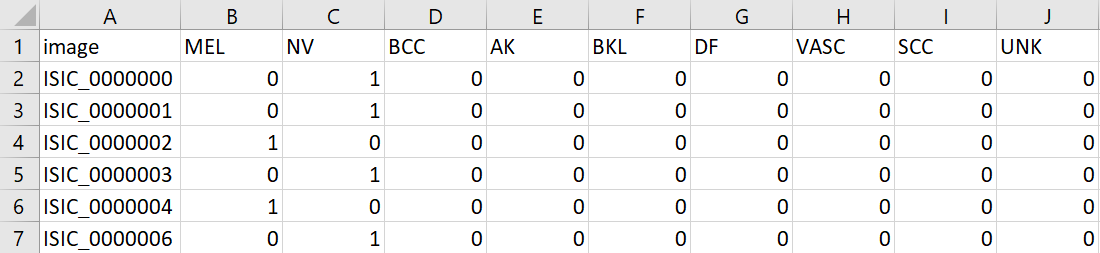

When assigning labels to an imageDatastore, we must supply them in a one-dimensional vector. Hence, we should collapse each logical row in the matrix to a single string that is the image's label. 

To avoid doing this every time this script is run, we have provided a helper script called [convertTruthLabels.mlx](matlab:open('./convertTruthLabels.mlx')) that converts the .csv file from the ISIC datset into a new .csv with the desired format. If you have not done so, please run that script now. 

**labelsLocations** should be set to the path of this converted file.

#### Import ground truth labels

groundtruth = readtable(labelsLocation); % Read the converted .csv file as a table
image_datastore.Labels = categorical(groundtruth.category); % Set the Labels of the imageDatastore to a categorical type array from the category column of .csv

Display some images with their true label

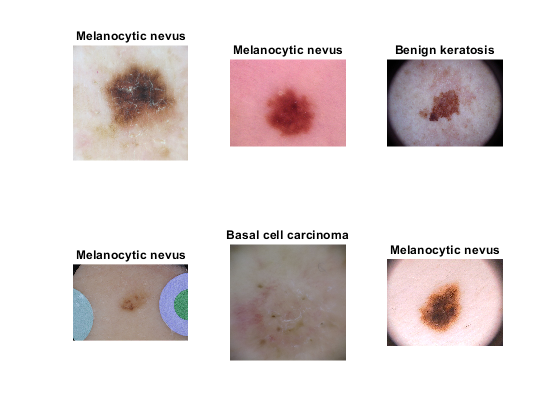

figure;
for i = 1:6
    subplot(2,3,i);
    sample_idx = randi(num_images);
    imshow(readimage(image_datastore, sample_idx)); % Extract the image file from the imageDatastore and imshow it
    title(image_datastore.Labels(sample_idx));
end

## Prepare dataset for model training

#### Split dataset into training set, validation set

MATLAB provides the [splitEachLabel](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.imagedatastore.spliteachlabel.html) to split an imageDatastore into training and validation (and test) sets. This works by taking images proportionally from each category, so each set has the same distribution of classification labels. 

[trainImds, valImds, testImds] = splitEachLabel(image_datastore, 0.8, 0.1); % Select 80% of each label into a new train set imageDatastore, the rest is split into validation and test sets

### Balance training set by oversampling underrepresented classes

As shown below, the ISIC dataset is highly imbalanced. 

Of our 8 classes, ~50% are of label 'Melanocytic nevus' (medical term for the common birthmark), ~18% are of label 'Melanoma'. Furthermore, our 4 smallest classes account for less than 8% of the total dataset combined. This is a problem as our model will heavily prefer to predict the larger classes purely by statistical likeliness. 

trainingLabelCounts = countEachLabel(trainImds) % Get the number of images that belong to each class label

trainingLabelCounts = 8×2 table
             Label             Count
    _______________________    _____

    Actinic keratosis            694
    Basal cell carcinoma        2658
    Benign keratosis            2099
    Dermatofibroma               191
    Melanocytic nevus          10300
    Melanoma                    3618
    Squamous cell carcinoma      502
    Vascular lesion              202


To address this issue, we ***oversample*** the training setset - create duplicate entries for each image in the smaller classes to make up the difference in size. We have provided a separate helper function [oversampleDataset.m](matlab:open('./oversampleDataset.m')) to do this and return the balanced imageDatastore.

targetLabelCount = max(trainingLabelCounts.Count); % the ceiling for oversampleDataset to duplicate each class label to
balTrainImds = oversampleDataset(trainImds, targetLabelCount);


Each category should have the same number of samples as the highest category (Mel. nevus). 

labelCounts = countEachLabel(balTrainImds)

labelCounts = 8×2 table
             Label             Count
    _______________________    _____

    Actinic keratosis          10300
    Basal cell carcinoma       10300
    Benign keratosis           10300
    Dermatofibroma             10300
    Melanocytic nevus          10300
    Melanoma                   10300
    Squamous cell carcinoma    10300
    Vascular lesion            10300


classes = labelCounts.Label;

#### Augment training images (and resize images to work with GoogLeNet)

Since we are performing transfer learning with GoogLeNet CNN, we must resize each image to fit the input layer size (224x224). 

inputSize = [224,224];

GoogLeNet is a deep CNN with many nodes. Being so complex, it will easily overfit to our training set. To mitigate this, one step we take is to "augment" our image samples.

These augmentations include flipping the images vertically and horizontally, rotating them around their center, zooming in/out slightly, and adding shear/skew to the images. 

To resize and augment our training set, we create an [augmentedImageDatastore](https://www.mathworks.com/help/deeplearning/ref/augmentedimagedatastore.html) by passing the desired image size, the imageDatastore, and an [imageDataAugmenter](https://www.mathworks.com/help/deeplearning/ref/imagedataaugmenter.html) that is configured with the augmentation settings.

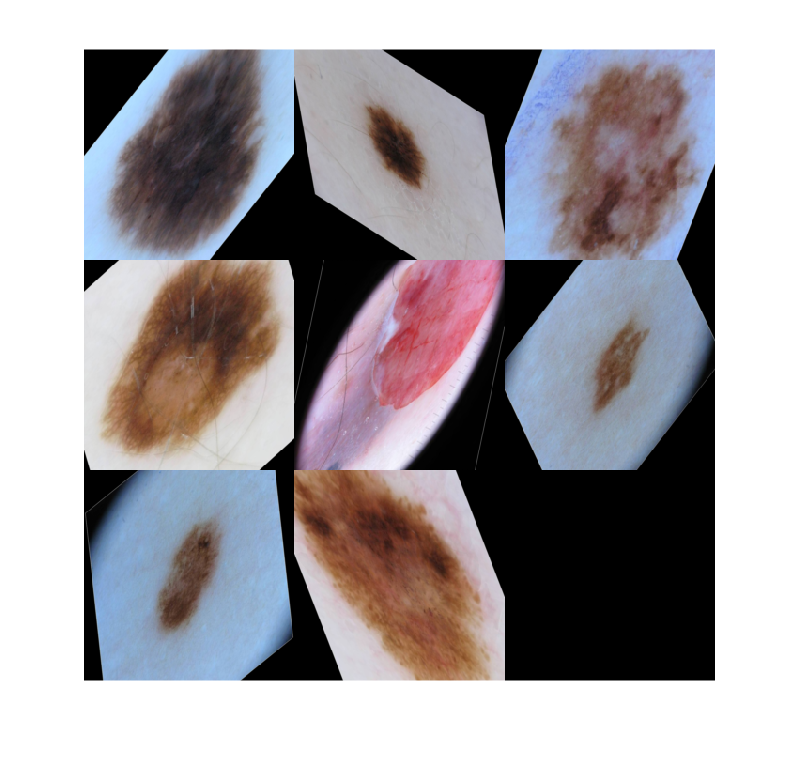

% Create the imageDataAugmenter with the desired augmentation effects.
% These effects are each applied at random.
% See the docs for in-depth descriptions of each Name, Value option pair. 
augmenter = imageDataAugmenter( ...
    "RandXReflection", true, ... 
    "RandYReflection", true, ...
    "RandRotation", [-180 180], ... % Rotate an image between +-180 degrees
    "RandScale", [0.8 1.5], ...     % Scale an image from 80% to 150% of its original size
    "RandXShear", [0 30], ...       % Shear an image horizontally and vertically within the range 0 degrees to 30 degrees
    "RandYShear", [0 30]);          


% Augment the training set with the determined inputSize and imageDataAugmenter
% Returned is a new type of object - augmentedImageDatastore
trainAugDs = augmentedImageDatastore(inputSize, balTrainImds,"DataAugmentation",augmenter);

% Preview some of the augmented images
figure;
minibatch = preview(trainAugDs);
imshow(imtile(minibatch.input));

#### Resize the validation set

Any image going through the GoogLeNet model needs to be 224x224, so we should resize the validation and test sets as well. 

valAugDs = augmentedImageDatastore(inputSize, valImds);
testAugDs = augmentedImageDatastore(inputSize, testImds);

## Import and modify pretrained Neural Network

To make GoogLeNet compatible with our training data, we change the last two layers to output classifications for our 8 labels. 

Import GoogLeNet

net = googlenet; % Import the googlenet DAGNet object from the Deep Learning Toolbox
lgraph = layerGraph(net); % Convert to a layerGraph object, which contains all the data for each layer of the Neural Network

Replace the final fullyConnectedLayer

newFc = fullyConnectedLayer(numel(classes),"Name","new_fc"); % Create a new fullyConnectedLayer with nodes for each class 
lgraph = replaceLayer(lgraph,"loss3-classifier",newFc); % Replace the existing fullyConnectedLayer

#### Implement weighted cross-entropy loss to address imbalanced dataset

If for some reason we do not oversample the training set, we avoid the aforementioned bias for larger classes by using weighted cross-entropy loss.

Essentially, the model is given a penalty for choosing one of the larger classes as its prediction. This penalty/weight is determined by the classes proportion of the total labelCount. 

classWeights = max(labelCounts.Count)* ones(1,numel(classes)) ./ labelCounts.Count';

Replace the classificationLayer

% Create a new classificationLayer with our class Labels and cross-entropy weights
newOut = classificationLayer("Name","new_out", "ClassWeights", classWeights, "Classes", classes); 
lgraph = replaceLayer(lgraph,"output",newOut); % Replace the existing classificationLayer

## Set training options

We will be using MiniBatch Gradient Descent with Momentum. Learn more about neural network training algorithms [here.](https://ruder.io/optimizing-gradient-descent/)

The other training options (known as hyperparameters) such as Learning Rate and Minibatch size are created and passed into the trainNetwork function. 

- Minibatch size - How many images are fed-foward before each weight adjustment step. Largely determined by the amount of available dedicated Video RAM.

- Learning Rate - How large each weight adjustment step is. Smaller is slower, but too large can lead to divergence from the optimal value. 

- L2Regularization - Penalizes neural network nodes with large weights, so that any one node won't have a large effect on the output. Reduces overfitting.

We also implement early stopping. At regular intervals throughout training, the model is tested against the validation set. When the average classification loss on the validation set stops improving, training stops and the model that performed best on the validation set is saved. 

miniBatchSize = 64;

validationsPerEpoch = 5;
validationPatienceEpochs = 7;

iterationsPerEpoch = floor(numel(trainAugDs.Files)/miniBatchSize);
validationFrequency = floor(iterationsPerEpoch/validationsPerEpoch);
validationPatience = validationsPerEpoch * validationPatienceEpochs;

options = trainingOptions("sgdm", ...
    "InitialLearnRate", 0.001, ...
    'MiniBatchSize',miniBatchSize,"Shuffle", "every-epoch", ...
    'MaxEpochs', 30, ...
    'Plots','training-progress',"L2Regularization", 1e-4, ... 
    "ValidationData", valAugDs, "ValidationFrequency",validationFrequency, ...
    "OutputNetwork","best-validation-loss", "ValidationPatience", validationPatience);

### Train the neural network

lesionNet = trainNetwork(trainAugDs, lgraph, options);

#### Save trained model to device. 

Including the imageDatastores allows for proper re-evaluation of the model, since the training-validation split is randomized every time the script is run. 

save lesionNet_prev.mat lesionNet options balTrainImds valImds trainAugDs valAugDs;

### Evaluate network on Validation set

Generate predictions for each image in the validation set. 

[preds, predScores] = classify(lesionNet, valAugDs);
valTrue = valImds.Labels;

#### Calculate performance metrics

Accuracy is the proportion of the images that were correctly classified. 

valAccuracy = nnz(preds == valTrue)/numel(preds)

In a confusion chart, each horizontal row represent a certain class of image. The numbers in the vertical columns represent how many of those images the model predicted to be in each class. Therefore, each number along the diagonal represents the correct, "true-positive" predictions. 

confusionchart(valTrue, preds, 'RowSummary','row-normalized', 'ColumnSummary','column-normalized','Title',"Validation Set - Accuracy: " + string(valAccuracy));

At the end of each row is the percent of images in that class that were correctly predicted, commonly known as the "recall" for that class. At the bottom of each column is the "precision", the proportion of correct classifications by the number of times the model predicted that class. 

Since the validation set is imbalanced, overall accuracy is not a clear picture of the models performance. Looking at recall and precision for each class gives a better metric by which to evaluate the models performance. 

F1 score is simply a weighted average of these two metrics: $\frac{2*\textrm{recall}*\textrm{precision}}{\textrm{recall}+\textrm{precision}}$.

Calculating Precision, Recall, & F1

confusion_matrix = confusionmat(valTrue, preds);

correct = diag(confusion_matrix);

precision = correct./sum(confusion_matrix)';
recall = correct./sum(confusion_matrix, 2);
f1Scores = 2*(precision.*recall)./(precision + recall);

stats = table( ...
    [classes; "Average"], ...
    [precision; sum(precision)/numel(precision)], ...
    [recall; sum(recall)/numel(recall)], ...
    [f1Scores; sum(f1Scores)/numel(f1Scores)], ...
    'VariableNames', {'Class', 'Precision', 'Recall', 'F1Score'})

### Performance Curve

AUC = zeros(8, 1);
for i=1:8

    [X, Y, T, AUC(i)] = perfcurve(valTrue, predScores(:, i), classes(i));
    
    plot(X,Y);
    hold on;
end

xlabel('False positive rate');
ylabel('True positive rate');
title('ROC for Classification with InceptionV3', ['Average AUC: ' num2str(mean(AUC))]);
legend([string(classes) + ' ' + num2str(round(AUC, 3))], 'Location','southeast');
hold off;

#### Representing malignant vs benign classification performance

We can convert this multiclass classification problem into a binary one by comparing benign and malignant diagnoses. (It should be noted that Actinic keratosis is technically "pre-malignant". We have decided to include it in the malignant class for simplicity.)

% Create a copy of our validation set true and predicted label. 
newValTrue = valTrue;
newPreds = preds;

% Categorical arrays to group each class
malignants = categorical(cellstr(["Actinic keratosis","Basal cell carcinoma", "Melanoma", "Squamous cell carcinoma"]));
benigns = categorical(cellstr(["Benign keratosis", "Dermatofibroma", "Melanocytic nevus", "Vascular lesion"]));

% If a label is in either group, replace that label with the new binary label
newValTrue(ismember(valTrue, malignants)) = 'Malignant';
newValTrue(ismember(valTrue, benigns)) = 'Benign';

newPreds(ismember(preds, malignants)) = 'Malignant';
newPreds(ismember(preds, benigns)) = 'Benign';

newValTrue = categorical(string(newValTrue));
newPreds = categorical(string(newPreds));

% Visualize the binary classification performance
confusionchart(newValTrue, newPreds, "ColumnSummary","column-normalized","RowSummary","row-normalized");

## Visualize predictions

Take a look at some of the images that the model incorrectly classified. 

failedPredictions = find(preds~=valTrue);
num_fail = numel(failedPredictions);
if ~isempty(failedPredictions)
    figure;
    for i = 1:6
        subplot(2,3,i);
        sample_idx = randi(num_fail);
        imshow(readimage(valImds, failedPredictions(sample_idx)), "InitialMagnification", 200);
        title({"True: " + string(valTrue(failedPredictions(sample_idx))),"Pred: " + string(preds(failedPredictions(sample_idx)))});
    end
end

### Visualize correct predictions

correctPredictions = find(preds==valTrue);
num_correct = numel(correctPredictions);
if ~isempty(correctPredictions)
    figure;
    for i = 1:6
        subplot(2,3,i);
        sample_idx = randi(num_correct);
        imshow(readimage(valImds,correctPredictions(sample_idx)), 'InitialMagnification', 100);
        title({"True: " + string(valTrue(correctPredictions(sample_idx))),"Pred: " + string(preds(correctPredictions(sample_idx)))});
    end
end

### Visualizing Network Predictions using Occlusion Sensitivity

Occlusion Sensitivity Mapping is a technique to visualize which parts of an image a model is "looking at" when it makes a prediction. It works by covering up (occluding) portions of the image and predicting outputs with each section covered. The map is created based on how this occlusion affects the confidence of the intended output (positively or negatively). 

In essence, portions highlighted in red promote a prediction of the selected class, while portions highlighted in blue deter the algorithm from predicting that class. 

Below we display the true label of a random image and the occlusion sensitivity for the top three predictions of that image. 

sample_idx = randi(numel(preds));

img = readimage(valImds, sample_idx);
img = imresize(img, [224, 224]);

[top_score, top_idx]  = maxk(predScores(sample_idx,:), 3);
top = classes(top_idx);

figure;
subplot(2,2,1);
imshow(img);
title(string(valTrue(sample_idx)));
for i = 1:3
    map = occlusionSensitivity(lesionNet,img,top(i));
    
    subplot(2,2,i+1);
    imshow(img,'InitialMagnification',100)


    hold on 
    imagesc(map,'AlphaData',.3)
    colormap jet
    colorbar
    title({"Occlusion sensitivity", sprintf("(%s, %.2f)", top(i), top_score(i))})
    hold off

end


## Evaluate network on Test Set

Since model picking, hyperparameter adjustments, and early stopping are tuned with regard to the validation set. Final "results" should come from performance on the test set. 

Generate predictions for each image in the test set. 

[preds, predScores] = classify(lesionNet, testAugDs);
testTrue = testImds.Labels;

#### Calculate performance metrics

Accuracy is the proportion of the images that were correctly classified. 

testAccuracy = nnz(preds == testTrue)/numel(preds)

testAccuracy = 0.7271

In a confusion chart, each horizontal row represent a certain class of image. The numbers in the vertical columns represent how many of those images the model predicted to be in each class. Therefore, each number along the diagonal represents the correct, "true-positive" predictions. 

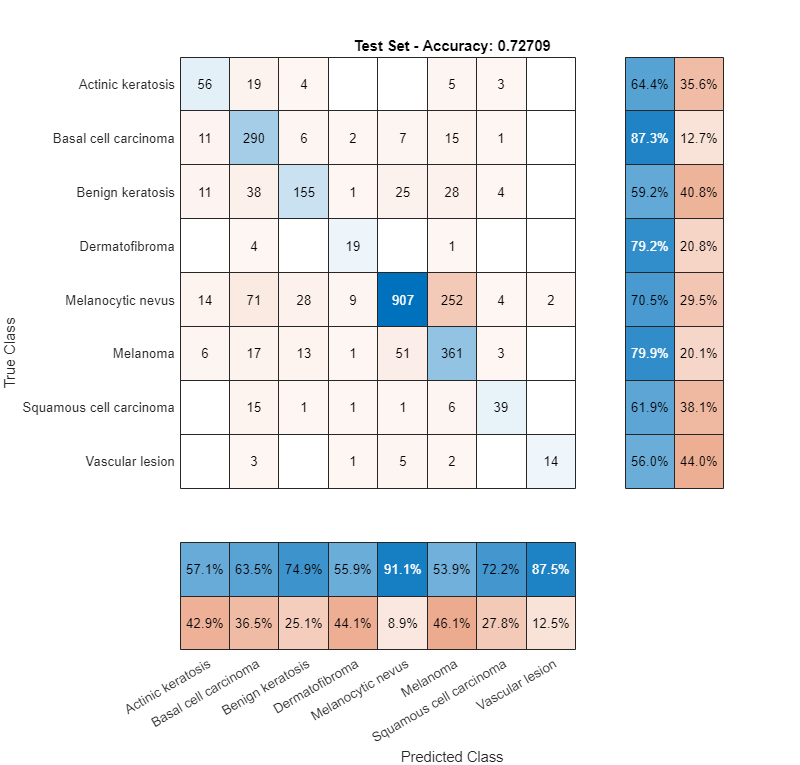

confusionchart(testTrue, preds, 'RowSummary','row-normalized', 'ColumnSummary','column-normalized','Title',"Test Set - Accuracy: " + string(testAccuracy));

Calculating Precision, Recall, & F1

confusion_matrix = confusionmat(testTrue, preds);

correct = diag(confusion_matrix);

precision = correct./sum(confusion_matrix)';
recall = correct./sum(confusion_matrix, 2);
f1Scores = 2*(precision.*recall)./(precision + recall);

stats = table( ...
    [classes; "Average"], ...
    [precision; sum(precision)/numel(precision)], ...
    [recall; sum(recall)/numel(recall)], ...
    [f1Scores; sum(f1Scores)/numel(f1Scores)], ...
    'VariableNames', {'Class', 'Precision', 'Recall', 'F1Score'})

stats = 9×4 table
             Class             Precision    Recall     F1Score
    _______________________    _________    _______    _______

    Actinic keratosis           0.57143     0.64368    0.60541
    Basal cell carcinoma        0.63457     0.87349    0.73511
    Benign keratosis            0.74879      0.5916    0.66098
    Dermatofibroma              0.55882     0.79167    0.65517
    Melanocytic nevus           0.91064     0.70474    0.79457
    Melanoma                    0.53881     0.79867    0.64349
    Squamous cell carcinoma     0.72222     0.61905    0.66667
    Vascular lesion               0.875        0.56    0.68293
    Average                     0.69504     0.69786    0.68054


### Performance Curve

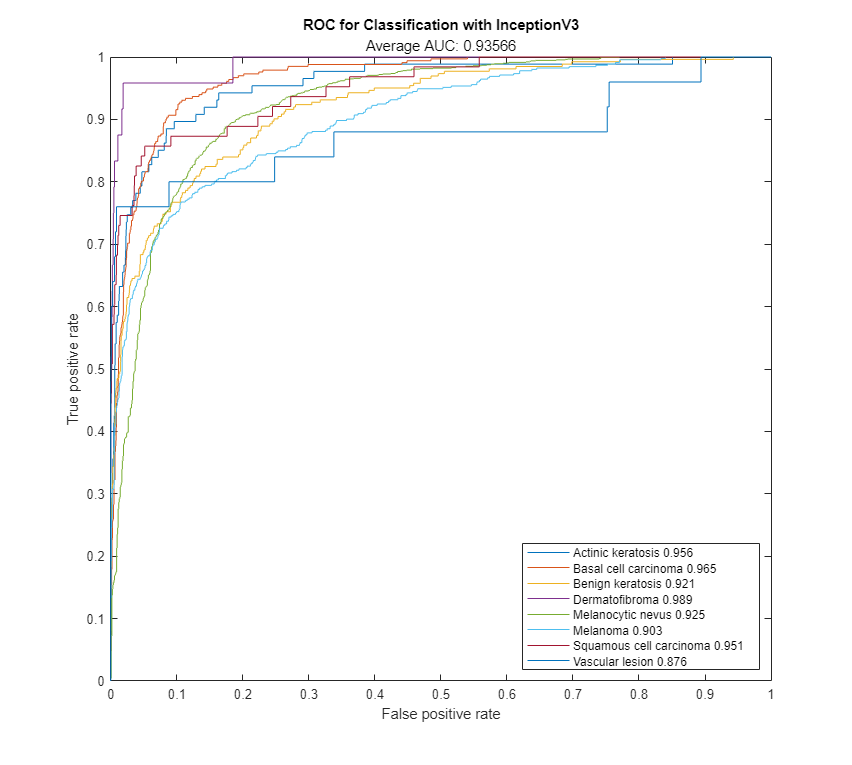

AUC = zeros(8, 1);
for i=1:8

    [X, Y, T, AUC(i)] = perfcurve(testTrue, predScores(:, i), classes(i));
    
    plot(X,Y);
    hold on;
end

xlabel('False positive rate');
ylabel('True positive rate');
title('ROC for Classification with InceptionV3', ['Average AUC: ' num2str(mean(AUC))]);
legend([string(classes) + ' ' + num2str(round(AUC, 3))], 'Location','southeast');
hold off;

#### Representing malignant vs benign classification performance

We can convert this multiclass classification problem into a binary one by comparing benign and malignant diagnoses. (It should be noted that Actinic keratosis is technically "pre-malignant". We have decided to include it in the malignant class for simplicity.)

% Create a copy of our test set true and predicted label. 
newTestTrue = testTrue;
newPreds = preds;

% Categorical arrays to group each class
malignants = categorical(cellstr(["Actinic keratosis","Basal cell carcinoma", "Melanoma", "Squamous cell carcinoma"]));
benigns = categorical(cellstr(["Benign keratosis", "Dermatofibroma", "Melanocytic nevus", "Vascular lesion"]));

% If a label is in either group, replace that label with the new binary label
newTestTrue(ismember(testTrue, malignants)) = 'Malignant';
newTestTrue(ismember(testTrue, benigns)) = 'Benign';

newPreds(ismember(preds, malignants)) = 'Malignant';
newPreds(ismember(preds, benigns)) = 'Benign';

newTestTrue = categorical(string(newTestTrue));
newPreds = categorical(string(newPreds));

% Visualize the binary classification performance
confusionchart(newTestTrue, newPreds, "ColumnSummary","column-normalized","RowSummary","row-normalized");